
clearvars;

% =========================================================================
% DEFINE LITERALS
% =========================================================================
    

% medium parameters
c0              = 1500;     % sound speed [m/s]
rho0            = 1000;     % density [kg/m^3]
u               = 0.04;

% source parameters
source_f0       = 500000;   % source frequency [Hz]
source_roc      = 15e-3;    % bowl radius of curvature [m]
source_diameter = 20e-3;    % bowl aperture diameter [m]
source_mag      = rho0*c0*u;% source pressure [Pa]
offset          = source_roc - sqrt((source_roc^2)-(source_diameter/2)^2);

% grid parameters
axial_size      = 64e-3;    % total grid size in the axial dimension [m]
lateral_size    = 32e-3;  % total grid size in the lateral dimension [m]

% computational parameters
ppw             = 13;        % number of points per wavelength
t_end           = 120e-6;    % total compute time [s] (this must be long enough to reach steady state)
record_periods  = 3;        % number of periods to record
cfl             = 0.05;     % CFL number

% =========================================================================
% RUN SIMULATION
% =========================================================================

% --------------------
% GRID
% --------------------

% calculate the grid spacing based on the PPW and F0
dx = c0 / (ppw * source_f0);   % [m]

source_x_offset = round(offset/dx); %grid points for offset of source 

% compute the size of the grid
Nx = roundEven(axial_size / dx) 

Nx = 278

%+ source_x_offset;
Ny = roundEven(lateral_size / dx);
% Nx = 120;
% Ny = 120;

% create the computational grid
kgrid = kWaveGrid(Nx, dx, Ny, dx);

% compute points per temporal period
PPP = round(ppw / cfl);

% compute corresponding time spacing
dt = 1 / (PPP * source_f0);

% create the time array using an integer number of points per period
Nt = round(t_end / dt);
kgrid.setTime(Nt, dt);

% calculate the actual CFL and PPW
disp(['PPW = ' num2str(c0 / (dx * source_f0))]);

PPW = 13


disp(['CFL = ' num2str(c0 * dt / dx)]);

CFL = 0.05


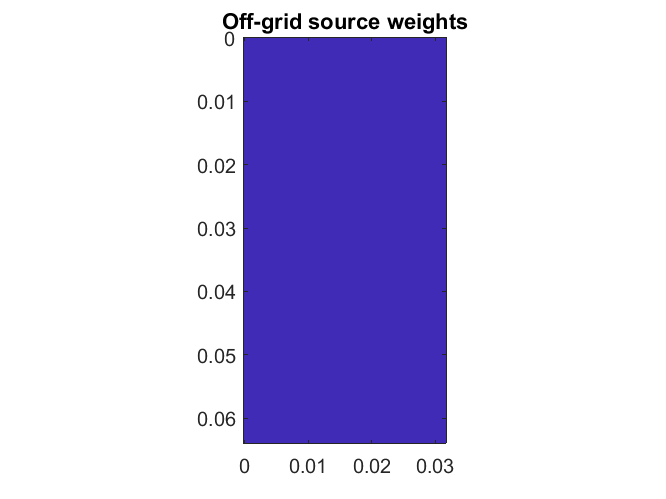


% --------------------
% SOURCE
% --------------------

% create time varying source
source_sig = createCWSignals(kgrid.t_array, source_f0, source_mag, 0);

%create empty kWaveArray
karray = kWaveArray('Axisymmetric', true, 'BLITolerance', 0.01);
source_diam     = 0.02; 
% add line shaped element
karray.addLineElement([kgrid.x_vec(1), -source_diam/2], [kgrid.x_vec(1), source_diam/2]);

% assign binary mask
source.p_mask = karray.getArrayBinaryMask(kgrid);

% assign source signals
source.p = karray.getDistributedSourceSignal(kgrid, source_sig);

% plot grid weights
grid_weights = karray.getArrayGridWeights(kgrid);
figure;
imagesc(kgrid.y_vec - kgrid.y_vec(1), kgrid.x_vec - kgrid.x_vec(1), grid_weights);
axis image;
title('Off-grid source weights');

Running k-Wave simulation...
  start time: 01-May-2022 15:43:29
  reference sound speed: 1500m/s
  dt: 7.6923ns, t_end: 119.9923us, time steps: 15600
  input grid size: 278 by 138 grid points (64.1538 by 31.8462mm)
  maximum supported frequency: 3.25MHz
  expanding computational grid...
  computational grid size: 324 by 162 grid points
  casting variables to single type...
  precomputation completed in 4.6352s
  starting time loop...
  estimated simulation time 27min 56.064s...


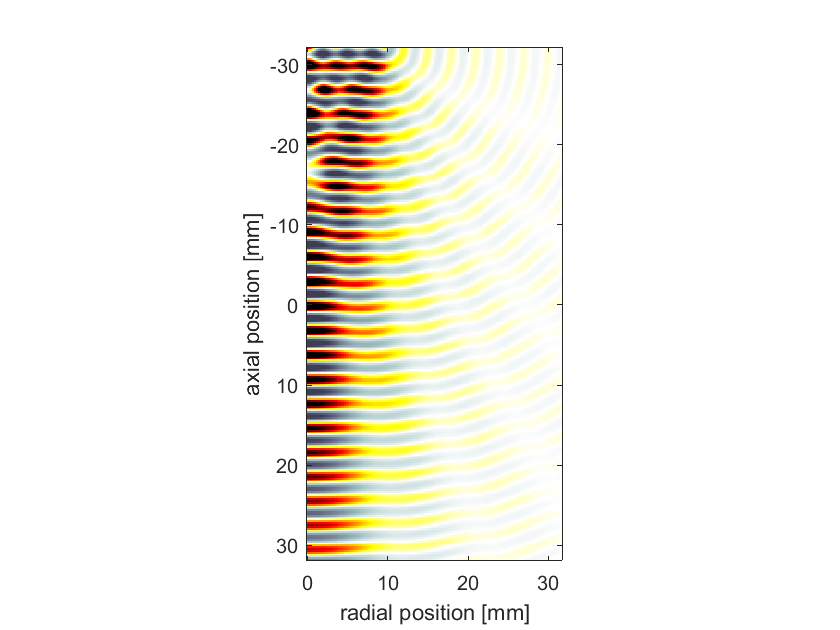

  simulation completed in 29min 25.6263s
  total computation time 29min 30.72s


    
% --------------------
% MEDIUM
% --------------------

% assign medium properties
medium.sound_speed = c0;
medium.density = rho0;
medium.alpha_power = 2;
% 
medium.alpha_coeff = 4;

% --------------------
% SENSOR
% --------------------

% set sensor mask to record central plane, not including the source point
sensor.mask = zeros(Nx, Ny);
sensor.mask(:, :) = 1;

% record the pressure
sensor.record = {'p'};

% --------------------
% SIMULATION
% --------------------

% set input options
input_args = {...
    'PMLSize', 'auto', ...
    'PMLInside', false, ...
    'PlotPML', false, ...
    'DisplayMask', 'off'};

% run code

sensor_data = kspaceFirstOrderAS(kgrid, medium, source, sensor, ...
    input_args{:}, ...
    'DataCast', 'single', ...
    'PlotScale', [-1, 1] * source_mag);


% extract amplitude from the sensor data
amp = extractAmpPhase(sensor_data.p, 1/kgrid.dt, source_f0, ...
    'Dim', 2, 'Window', 'Rectangular', 'FFTPadding', 1);

% reshape data
amp = reshape(amp, Nx, Ny);

% extract pressure on axis
amp_on_axis = amp(:, 1);

% define axis vectors for plotting
x_vec = kgrid.x_vec(source_x_offset + 2:end, :) - kgrid.x_vec(source_x_offset + 1);
y_vec = kgrid.y_vec - kgrid.y_vec(1);


% % =========================================================================
% % Extracting Pressure and Time Data
% =========================================================================
x_vec = kgrid.x_vec(2:end, :) - kgrid.x_vec(1);

timeperiod= 0:dt:t_end-dt;
periodofwave = 1/source_f0;
cyclelength = periodofwave/dt;
timeindex = Nt-(cyclelength-1);
wavetime = timeperiod(timeindex:Nt);
samplingfrequency = 1/dt;
freqv = (0:cyclelength/2-1)*samplingfrequency/cyclelength;
FFTarray = [];
FFTmag = [];
for i=1:Nx-1
    pressuretime = sensor_data.p(i, 1:Nt);
    cycleextract = pressuretime(timeindex:Nt);
    FFT = fft(cycleextract);

    %symmetric so remove second half
    FFT = FFT(1:cyclelength/2);
    
    %magnitude of fft
    mFFT = (abs(FFT));
    scaledFFT = mFFT*(2/PPP);
    [FFTpeak, FFTindex] = max(scaledFFT);
    peakfreq = freqv(FFTindex);
    FFTarray = [FFTarray,peakfreq];
    FFTmag = [FFTmag,FFTpeak];
end





% plot the pressure field 

% duplicate the pressure field
amp = [flip(amp(:, 2:end), 2), amp];
y_vec = [-flip(y_vec(2:end)); y_vec];

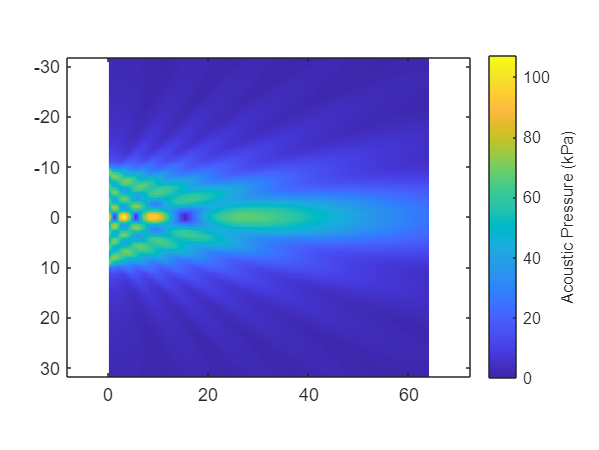

figure;
imagesc(1e3 * x_vec, 1e3 * y_vec, 1e-3*amp.');
%xlabel('Axial Position [mm]');
%ylabel('Lateral Position [mm]');
axis equal;
%title('Acoustic Pressure Field with a heterogeneous medium of complex cranial geometry and focused bowl source generated using k-Wave');
a = colorbar;
a.Label.String = 'Acoustic Pressure (kPa)';
caxis([0 107])

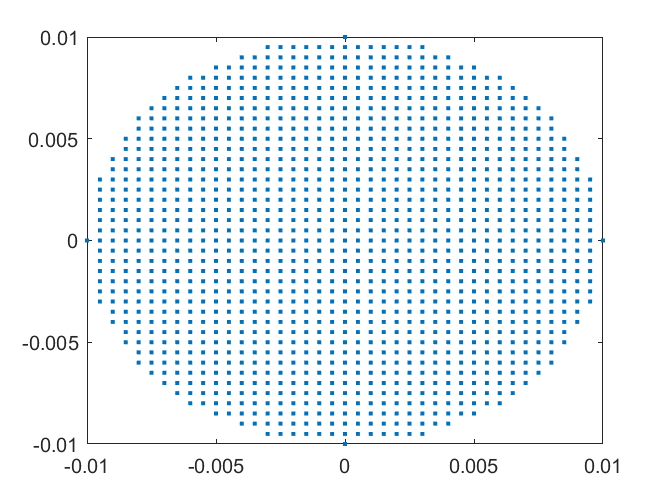

%%%==================================%%%
%$% Rayleigh's Integral Discretised %%$$$%


%% Variables %%
m=41;
a=0.01;
b=0.12;
w = 311;
%w = 104;
c = 1500;%speed of sound
f = 500000; %frequency
%k = (2*pi*f/c);%wave number
A = (4*100)/(20*log10(exp(1)));

B = 2;

alpha = A*((f*1e-6)^B);
omega = (2*pi*f);
k = omega/c;%complex wave number
kcomplex = k -(1i*alpha);
%k = (2*pi*f/c);%wave number
%% Non attenuated
%k = (2*pi*f/c);%wave number
ww = c/f; %wavelength = speed/frequency
p0 = 1000; %density of water
c = omega/kcomplex;
%% 3D coordinates %%
u = [0.04,0,0];%velocity vector
n = [1, 0, 0]; %normal vector with positive x axis being the axis of propagation
v = dot(u,n); %dot product of velocity vector with normal vector
% x2=linspace(0,0.1,w);
% y2=linspace(-0.02,0.02,w/1.5);
% z2=linspace(0,0.1,w);
% [X,Y,Z]=meshgrid(x2,y2,z2);
x2=linspace(0,0.064,w);
y2=linspace(-0.032,0.032,w);
z2=linspace(0,0.064,w);
[X,Y,Z]=meshgrid(x2,y2,z2);
sz = size(X);
P = zeros(sz); %creates matrix for receiver coordinates to sum all the values calculated below for each coordinate
y=linspace(-a,a,m);
z=linspace(-a,a,m);
[Y1, Z1]=meshgrid(y,z); 
yb=reshape(Y1,m^2,1);
zb=reshape(Z1,m^2,1);
n=find(yb.^2+zb.^2>a^2);
yb(n)=[];
zb(n)=[];
plot(yb,zb,'.') %planar piston

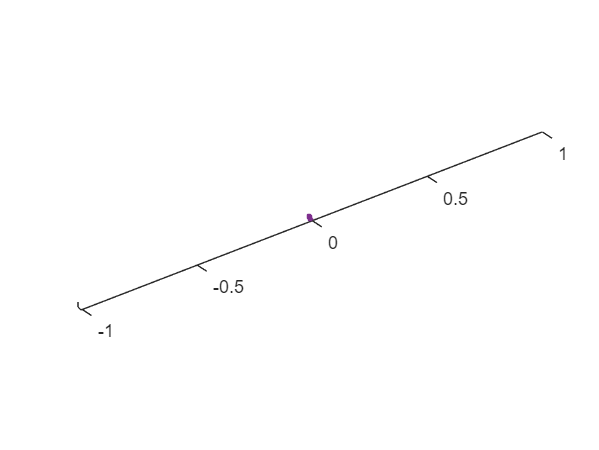

xb = zeros(length(yb));
plot3(xb,yb,zb,'o','MarkerSize',1)
axis equal

pistonarea = pi*(a^2);

%% Pressure calculation %%
g = pistonarea/length(xb);

t = 1;


for j=1:length(xb)
    P = P + ((((1i*p0*c*kcomplex)/(2*pi)).*((((exp(-1i.*((omega*t)-(sqrt((((xb(j)-X).^2)+(((yb(j))-Y).^2)+((zb(j))-Z).^2))).*k)))./(sqrt(((xb(j)-X).^2)+(((yb(j))-Y).^2)+((zb(j)-Z).^2)))).*v.*g))).*exp((-alpha.*(sqrt((((xb(j)-X).^2)+(((yb(j))-Y).^2)+((zb(j))-Z).^2))))));
end
% for j=1:length(yb)
%         P = P + (((1i*p0*c*k)/(2*pi)).*((((exp((sqrt((((xb(j)-X).^2)+(((yb(j))-Y).^2)+((zb(j))-Z).^2))).*k.*-1i))./(sqrt(((xb(j)-X).^2)+(((yb(j))-Y).^2)+((zb(j)-Z).^2)))).*v.*g)));
% end

PP = abs(P);
pd = squeeze(PP(156,:,1));

figure;
plot(x2*10^3,pd/10^3);
title('Comparison of the Magnitude of Acoustic Pressure of Bowl Source from Rayleigh Integral and k-Wave')
xlabel('Axial Position (mm)')
ylabel('Acoustic Pressure [kPa]')
%xlim([0 54])
hold on
plot(x_vec(1:276)*10^3,FFTmag(2:end)/10^3)
%plot(x_vec*10^3,FFTmag1/10^3)
legend('Rayleigh Integral Solution','Non-attenuated on-axis pressure','k-Wave Solution')

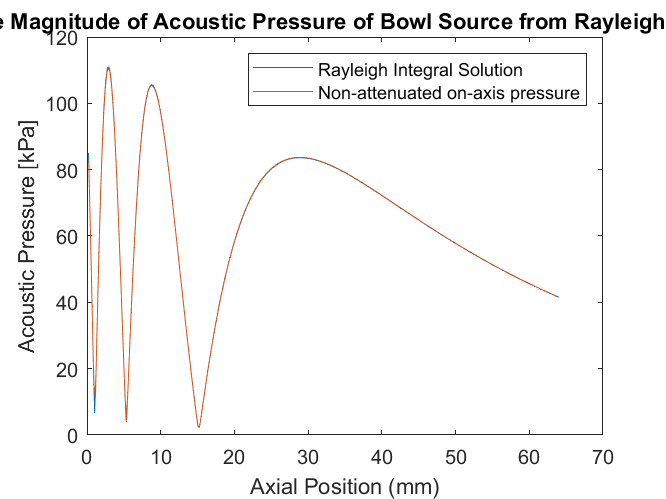

hold off

% % positionarrayanalysis = positionarray(2:280);
% % x2analysis = x2(2:280);
% % pdanalysis = pd(2:280);
% % FFTanalysis = FFTmag(2:280);
% % D = (pdanalysis-FFTanalysis).^2;
% % S1= sum(D);
% % S2 = sum((pdanalysis).^2);
% % ctest = 100*(sqrt(S1/S2));
% % MM = [ctest,MM];
% % plot(MM);

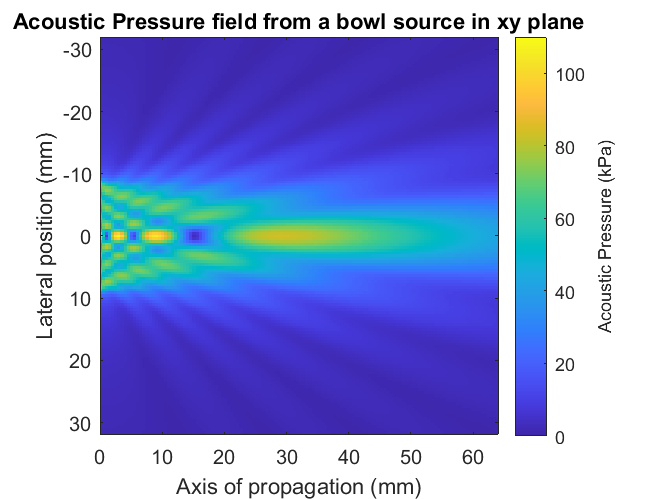

load('kwaveverified.mat','p_amp','p_phase','simulation_settings','general_settings')
%% Plotting slice of xy plane %%
imagesc(x2*1e3,y2*1e3,transpose(p_amp(1:128,:,1))*1e-3);
%slice(X*1e03,Y*1e03,Z*1e03,PP*1e-03,xslice,yslice,zslice)
shading flat
a = colorbar;
a.Label.String = 'Acoustic Pressure (kPa)';
axis equal
xlim([0 64])
ylim([-32 32])
caxis([0 110])
title('Acoustic Pressure field from a bowl source in xy plane')
xlabel('Axis of propagation (mm)')
ylabel('Lateral position (mm)')

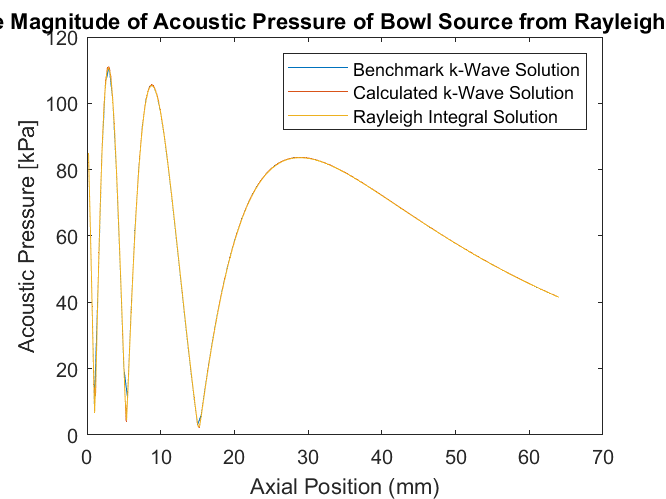

figure;
xxxx = 5e-4:5e-4:64e-3;
plot(xxxx*10^3,p_amp(2:129,71)/10^3);
title('Comparison of the Magnitude of Acoustic Pressure of Bowl Source from Rayleigh Integral and k-Wave')
xlabel('Axial Position (mm)')
ylabel('Acoustic Pressure [kPa]')
%xlim([0 54])
hold on
plot(x_vec(1:276)*10^3,FFTmag(2:end)/10^3)
plot(x2*10^3,pd/10^3)
%plot(x_vec*10^3,FFTmag1/10^3)
legend('Benchmark k-Wave Solution','Calculated k-Wave Solution','Rayleigh Integral Solution')
hold off

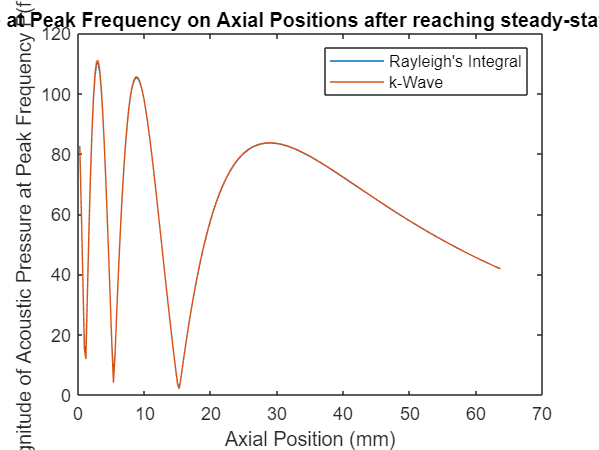

figure
vq2 = interp1(x2(2:end),pd(2:end),x_vec(1:276));
plot((x_vec(1:276)*10^3),vq2/10^3)
hold on 
plot((x_vec(1:276)*10^3),FFTmag(2:end)/10^3)
ylabel('Magnitude of Acoustic Pressure at Peak Frequency P(f) [kPa]')
xlabel('Axial Position (mm)')
title('Acoustic Pressure at Peak Frequency on Axial Positions after reaching steady-state with a bowl piston')
legend("Rayleigh's Integral",'k-Wave')
%xlim([0 59.5])
hold off

pctError = mean((abs(transpose(FFTmag(20:250))-vq2(19:249))./vq2(19:249))*100)

pctError = single
0.4835

D = (vq2(19:249)-(transpose(FFTmag(20:250)))).^2;
S1= sum(D);
S2 = sum((vq2(19:249)).^2);
ctest = 100*(sqrt(S1/S2))

ctest = single
0.3093

standdev = std((abs(transpose(FFTmag(20:250))-vq2(19:249))./vq2(19:249))*100)

standdev = single
2.7610

pctError = mean((abs(transpose(FFTmag(2:end))-vq2))./vq2*100)

pctError = single
0.5397

D = (vq2-(transpose(FFTmag(2:end)))).^2;
S1= sum(D);
S2 = sum((vq2).^2);
ctest = 100*(sqrt(S1/S2))

ctest = single
0.4387

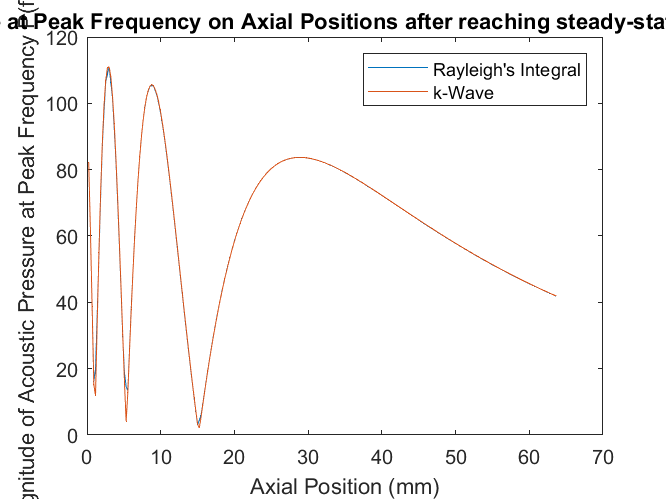

figure
vq2 = interp1(xxxx,p_amp(2:129,71),x_vec(1:276));
plot((x_vec(1:276)*10^3),vq2/10^3)
hold on 
plot((x_vec(1:276)*10^3),FFTmag(2:end)/10^3)
ylabel('Magnitude of Acoustic Pressure at Peak Frequency P(f) [kPa]')
xlabel('Axial Position (mm)')
title('Acoustic Pressure at Peak Frequency on Axial Positions after reaching steady-state with a bowl piston')
legend("Rayleigh's Integral",'k-Wave')
%xlim([0 59.5])
hold off

pctError = mean((abs(transpose(FFTmag(20:250))-vq2(19:249))./vq2(19:249))*100)

pctError = single
0.8833

D = (vq2(19:249)-(transpose(FFTmag(20:250)))).^2;
S1= sum(D);
S2 = sum((vq2(19:249)).^2);
ctest = 100*(sqrt(S1/S2))

ctest = single
1.1101

standdev = std((abs(transpose(FFTmag(20:250))-vq2(19:249))./vq2(19:249))*100)

standdev = single
6.0042

pctError = mean((abs(transpose(FFTmag(2:end))-vq2))./vq2*100)

pctError = single
NaN

D = (vq2-(transpose(FFTmag(2:end)))).^2;
S1= sum(D);
S2 = sum((vq2).^2);
ctest = 100*(sqrt(S1/S2))

ctest = single
NaN

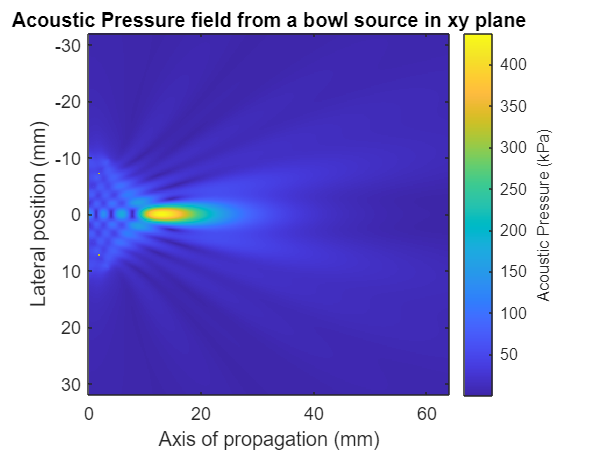

load('RayleighFocNona.mat','pd','vq2','FFTmag','x_vec',"pctError",'amp')
imagesc(x2*1e3,y2*1e3,PP(:,:,1)*1e-3);
%slice(X*1e03,Y*1e03,Z*1e03,PP*1e-03,xslice,yslice,zslice)
shading flat
a = colorbar;
a.Label.String = 'Acoustic Pressure (kPa)';
axis equal
xlim([0 64])
ylim([-32 32])
title('Acoustic Pressure field from a bowl source in xy plane')
xlabel('Axis of propagation (mm)')
ylabel('Lateral position (mm)')